a = 0;
b = pi/2;
p = (a+b)/2;

while (1)
    % escape the loop if p is the root
    if (myfun(p)) == 0
        break
    end

    % updade a and b
    if myfun(a)*myfun(p) < 0
        b = p;
    else
        a = p;
    end

    % set new p
    new_p = (a+b)/2;
    
    % escape the loop if relative difference is smaller than 10^(-3)
    if (rel_dif(p, new_p) < 10^(-3))
        p = new_p;
        break
    end

    % update p
    p = (a+b)/2;
end

% print
fprintf("Aprroximated root is %f\n", p);

Aprroximated root is 1.306185

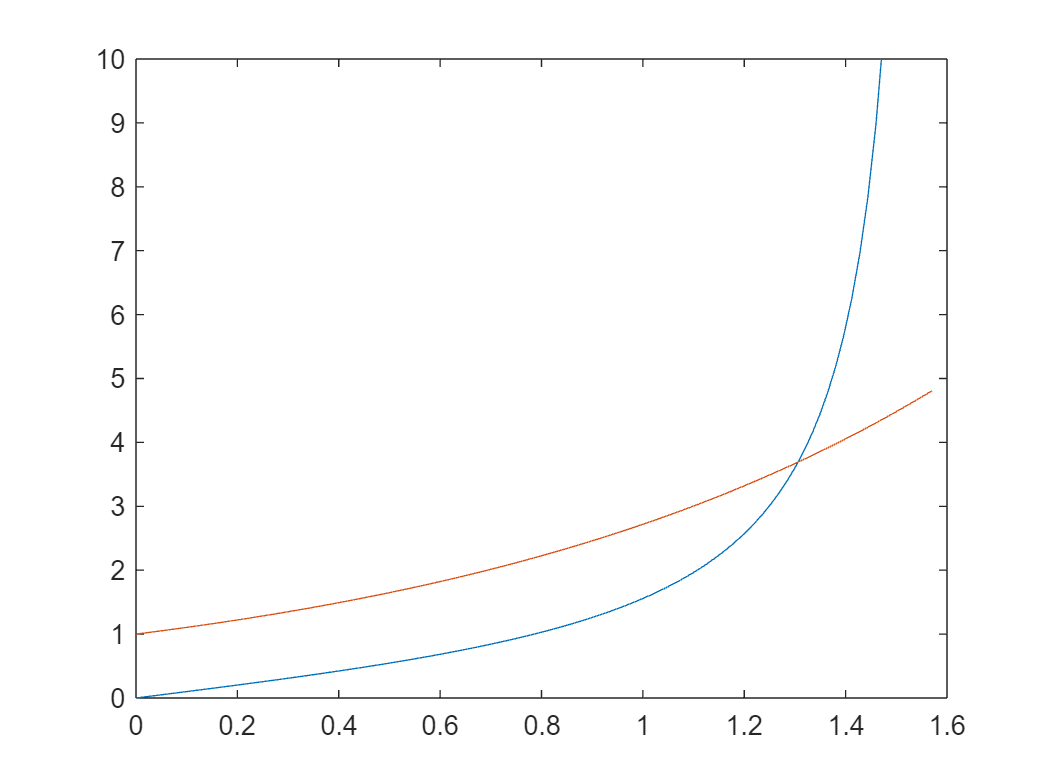


% display the graph
x = linspace(0,pi/2);
y1 = tan(x);
y2 = exp(x);
plot(x,y1,x,y2)
ylim([0 10])

function val = myfun(x)
    val = tan(x) - exp(x);
end

function dif = rel_dif(x1, x2)
    dif = abs(x2-x1)/abs(x1);
end
